clear; clc; 

T = 333; 
P = 101; 
global Rgas 
Rgas = 8.314; 

Feed_C2H4    =  (340+6.87)/3600*1000; % kgmole/hr
Feed_Cl2     =  (340+1.75)/3600*1000;
Feed_C2H4Cl2 = 2678/3600*1000;
Feed_C2H3Cl3 = 7.31/3600*1000;
Feed_HCl     = 7.31/3600*1000;

Feed_tot = Feed_C2H4 + Feed_Cl2 + Feed_C2H4Cl2 + Feed_C2H3Cl3 + ...
    Feed_HCl; 

V = 25.9876/3600; 

Dr = 5; 
Lr = 40; 
A  = pi*Dr^2/4 ; 
Vr = A*Lr;
Ug = V/A; 

ka = 0.467* Ug ^0.82; 

IC = [Feed_C2H4Cl2; Feed_HCl; Feed_C2H4; Feed_Cl2; Feed_C2H3Cl3]; 
iter = 200; 

% for i =1:iter-2
% for  j =2:iter-2

M  = eye(length(IC),length(IC)); 
Hspan = linspace(0,Lr, iter); 
Rgas = 8.314; 
options = odeset('Mass',M); 
BBanon  = @(h,y) DirectSolver(h,y,ka,A,T);
[h, ysoln] = ode15s(BBanon,Hspan,IC,options);





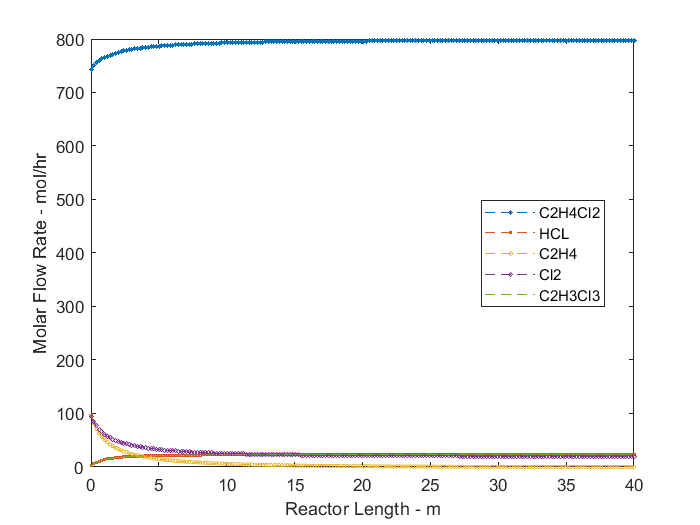


% Unpack solution
MflowC2H4Cl2 = ysoln(:,1);
MflowHCL     = ysoln(:,2);
MflowC2H4    = ysoln(:,3);
MflowCl2     = ysoln(:,4);
MflowC2H3Cl3 = ysoln(:,5);
Mflow_tot = sum([ MflowC2H3Cl3 MflowC2H4 MflowC2H4Cl2 MflowCl2 MflowHCL]);
Conv = (Feed_C2H4-MflowC2H4)/Feed_C2H4*100;
% end
% if Conv(j) >= 99.5
%     break
%     disp(i)
% end
% end
figure(2) % Molar Flows Profile
K = plot(h,MflowC2H4Cl2,'--*',h,MflowHCL,'--sq',h,MflowC2H4,'--o',h,MflowCl2,'--d',h,MflowC2H3Cl3,'--.');
grid off
xlabel('Reactor Length - m')
ylabel('Molar Flow Rate - mol/hr')

legend('C2H4Cl2','HCL','C2H4','Cl2','C2H3Cl3','Location','best')
K(1).MarkerSize = 2; 
K(2).MarkerSize = 2; 
K(3).MarkerSize = 2; 
K(4).MarkerSize = 2; 
K(5).MarkerSize = 2; 

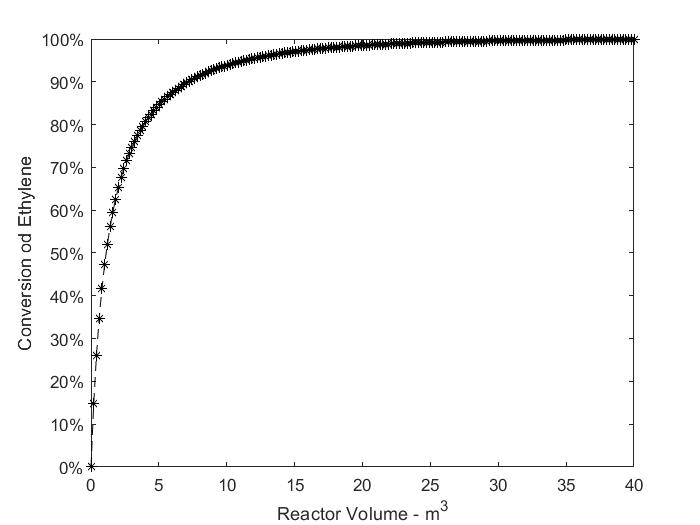


figure(3)
plot(h,Conv,'k--*')
grid off
xlabel('Reactor Volume - m^3');
ylabel('Conversion od Ethylene'); ytickformat('percentage');

K = [1.02380132906862e-002	8.34090991907975e-002	8.16643912294040e-002	1.77458915741338e-002]; 
Kavg = mean(K); Cp_liq = 106; % kJ/kmol-C
rho_liq = 1250; % kg/m^3
mu_liq  = 0.435; 
Db = 0.007; % (Mohagheghian et al., 2018)
Grav = 9.8; 
rho_C2H4    = 1.157; % kg/m^3 at 20 C
rho_Cl2     = 2.994; 
rho_gas = mean([rho_C2H4 rho_Cl2]); 
ub = (1/18) * Db^2 * rho_liq * Grav / mu_liq; 
Eps_g = Ug / (ub) 

Eps_g = 0.0048

Vf = ( Db * (pi/6/Eps_g) / 2.5 * (rho_liq - rho_gas)/rho_liq * Grav * Dr * Ug )^(1/3); 
% Heat Transfer Coefficient and Heat Duty
h = 0.18 * (1 - Eps_g) * ( (Kavg^2 * rho_liq^2 * Cp_liq * Vf^2)/(Db * (pi/6 /Eps_g)^(1/3) * mu_liq) ) ^(1/3) % W/m^2 - K 

h = 16.8065

Q = h*60 % W/m^2 

Q = 1.0084e+03

% Pressure Drop 
dP = (rho_gas*Eps_g + rho_liq*Eps_g) * Grav * Lr /1000 % kPa

dP = 2.3539


Vflow_out = 241.691069511598; % m^3/hr from HYSYS

disp(Conv(end))

   99.8747



disp(Vr/Vflow_out*3600) % residence time in seconds 

   1.1699e+04




% Yield 
TotFlowl = Feed_tot; 
PC2H4Cl2 = (MflowC2H4Cl2./TotFlowl).*P;
PHCL = (MflowHCL./TotFlowl).*P;

PC2H4 = (MflowC2H4./TotFlowl)*P;

PCl2 = (MflowCl2./TotFlowl).*P;
PC2H3Cl3 = (MflowC2H3Cl3./TotFlowl).*P;

CC2H4Cl2  = PC2H4Cl2./(Rgas*T)*1000; % mol/m^3
CHCL      = PHCL./(Rgas*T)*1000;
CC2H4     = PC2H4./(Rgas*T)*1000;
CCl2      = PCl2./(Rgas*T)*1000;
CC2H3Cl3  = PC2H3Cl3./(Rgas*T)*1000;

r1 = 0.132 * CC2H4.*CCl2           ; %mol/(m^3 s)
r2 = 0.0239 * CC2H4.*(CCl2).^2     ;
r3 =  6.12*10^(-9)* CC2H4Cl2.*CCl2;

Yield = (r1(end) -r3(end) + ka * CC2H4(end) + ka*CCl2(end) ) /( 2*r2(end) + 2*r3(end) + r1(end) -r3(end) + ka * CC2H4(end) + ka*CCl2(end)  ) 

Yield = 0.8838

Yield2 = (MflowC2H4Cl2(end)/Feed_C2H4Cl2)

Yield2 = 1.0717